# Tracking grooving tool vibrations using edge-detection

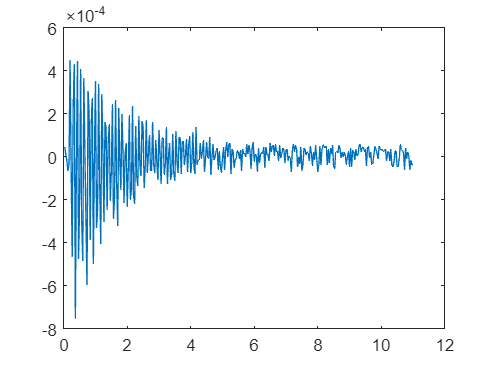

vid = VideoReader("Grooving.mp4","CurrentTime",15);
dispData = [];
time = [];
while (vid.CurrentTime < 26)
    frame = readFrame(vid);
    frame = im2gray(frame);
    frame = frame(97:177,450:490);
    frameEdge = edge(frame,"canny");
    xpix = find(frameEdge);
    xpix = xpix/82;
    xworld = xpix*(37.5e-6) + 18.75e-6;
    x = mean(xworld);
    dispData = [dispData,x];
    time = [time,vid.CurrentTime-15];
end
offset = mean(dispData);
dispData = dispData - offset;
plot(time,dispData);

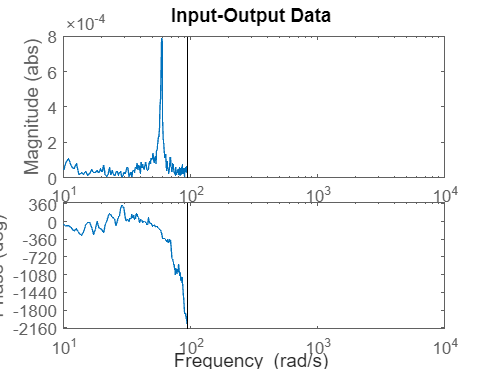

data = iddata(dispData',[],time(2)-time(1));
freqData = fft(data);
plot(freqData);
xlim([10,10000]);